clc;
close all;

Task 1:

We can hear the echo in the audio file

Fs = 48000;
[x,Fs] = audioread("speech.wav");

%Here I normalize the x signal
maxValue = max(abs(x));
x = x/maxValue;

Ne = 0.5*Fs; %% this is our echo delay
y = 0.7.*x;
y(Ne:end) = y(Ne:end) + 0.3.*x(1:(end-Ne+1));
%sound(y,Fs)

Task 2:

The difference between the two signals is w has a hot bar at 0.1 Normalized Frequency. 

In the Spectrogram of X we can see the signal before the sinusoid was added. 

In the Spectrogram of w we can see the results of adding a sinusoid to the x signal. 

    The 0.1 Normalized Frequency corresponds to 2.4KHz which is the frequency the sinusoid is at. This results in a delta spike at which we see in the Spectrogram of w at 2.4KHz. 

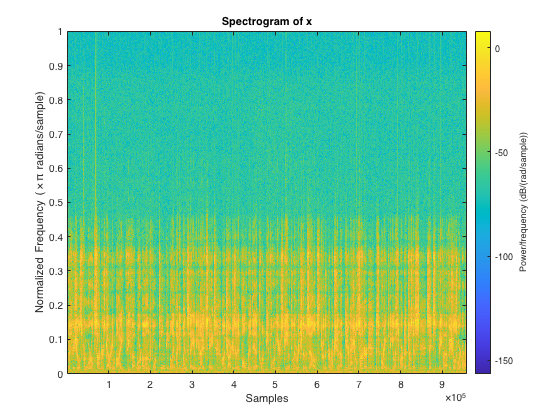

f1 = 2400;
L = length(x);
v = generate_sigs(f1,Fs,L);
v = v';
w = x + v;

%Spectrogram of x
window = 1000;
spectrogram(x,window,(0.25*window),'yaxis')
title("Spectrogram of x")
print -depsc spectrogramTask2x

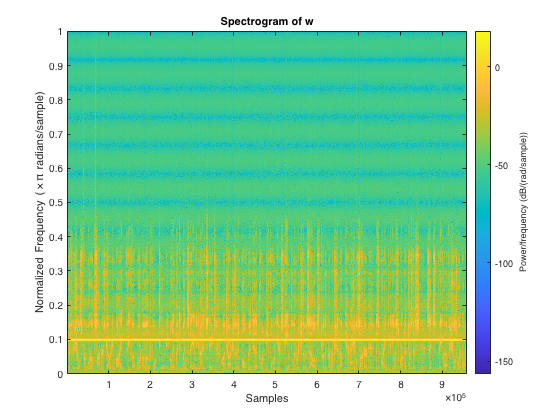


%Spectrogram of w
window = 1000;
spectrogram(w,window,(0.25*window),'yaxis')
title("Spectrogram of w")
print -depsc spectrogramTask2w

Task 3:

[https://drive.google.com/drive/folders/1NOy-Zgg3CYh2pV4HDXtoWGLrMMfF2vlo?usp=sharing](https://drive.google.com/drive/folders/1NOy-Zgg3CYh2pV4HDXtoWGLrMMfF2vlo?usp=sharing)

Feb the 3rd lecture last two slides.

FIR from IIR 

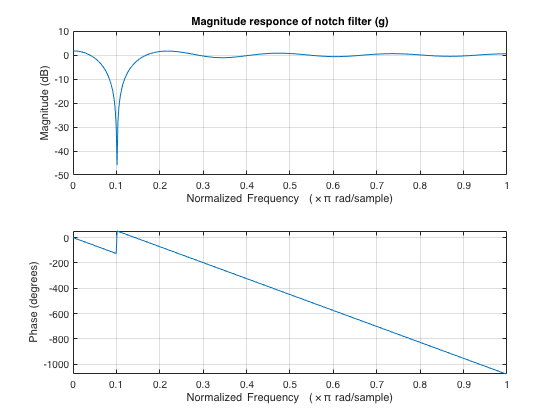

%Calculate the cuttoff frequency
wc = (2400/48000)*2*pi;
%Create number of samples for time domain filter (h)
%we want a 14 order filter so n = -7:7
n = -7:7;
h = sin(wc.*n)./(pi.*n);
% at n = 0 we get a NaN bc dived by zero so we need to hard code this 
h(8) = wc/pi;
% no we manipulate h to make a notch filter
g = 2*h;
%no subtract the delta to make the notch
g(8)= g(8)-1;
%Look at teh magnitude resp of g, the denom is 1 bc its FIR filter
freqz(g,1)
title("Magnitude responce of notch filter (g)")
print -depsc freqzTask3

Task 4:

We can see that we attenuated the signal at 0.1 Normalized frequency (i.e. 2.4KHz frequency). 

The bar is not as bright which indicated attenuation.

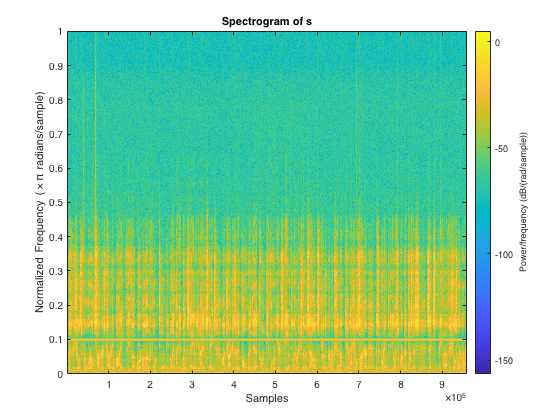

s = fir_filter(w,g);
%Spectrogram of s
window = 1000;
spectrogram(s,window,(0.25*window),'yaxis')
title("Spectrogram of s")
print -depsc spectrogramTask4s

Task 5:

The spectrogram shows the delta spike at 2.kHz(or 0.1 Normalized Frequency) has been greatly attenuated.

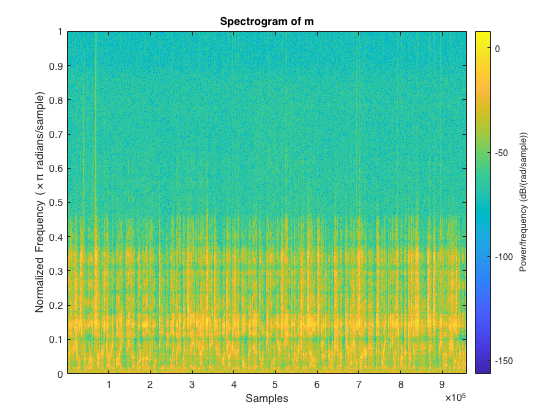

theta = 0.05*2*pi;
r = 0.98;
a = [1,-2*cos(theta),1];
b = [1,-2*r*cos(theta),r*r];
m = iir_filter(w,a,b);
sound(m,Fs);
%Spectrogram of m
window = 1000;
spectrogram(m,window,(0.25*window),'yaxis')
title("Spectrogram of m")
print -depsc spectrogramTask5m

function x = generate_sigs(f,Fs,L)
    t = 0:1/Fs:L/Fs - 1/Fs ; 
    x = cos(2*pi*f*t); 
end

function fir = fir_filter(w,h)
y = zeros(length(w),1);
 
    for n = (15):(length(w))
        for i = 1:(15)
            y(n) = y(n) + h(i)*w(n-i+1);
        end 
    end
    fir = y;
end


function filtered = iir_filter(x,a,b)
    y = [];
    %calc the first 2 terms
    y(1) = (a(1)*x(1))/b(1);
    y(2) = (a(1)*x(2) + a(2)*x(2-1) - b(2)*y(2-1))/b(1);
   
    for n = (3):(length(x))
        y(n) = (a(1)*x(n) + a(2)*x(n-1) + a(3)*x(n-2) - b(2)*y(n-1) - b(3)*y(n-2))/ b(1);
    end
    filtered = y;
end